# Figure 2 - Fluorescence is about 10x more than intense than reflectance

*(Tongue and lip reflectance data were measured and analyzed in s_lipTongueReflectanceXXXX.m).*

To measure lip and tongue fluorescence we needed to remove any reflected light from the light source.  These were always below 475nm, so added a 475 nm long pass to the system.  This blocked the reflected light, but allowed fluorescent light to pass. For more explanation, see Figure 1.

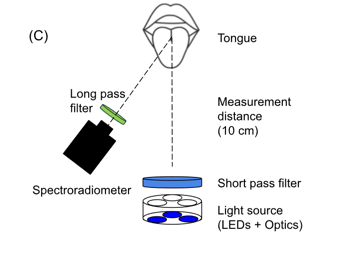

**Caption:** The six panels show the different measurement conditions.  The three columns show data acquired with each of three excitation lights (405 nm, 415 nm, 450nm).  The two rows show data acquired from the lip (top) and the tongue (bottom). The four curves in each panel show data from four different subjects, all measured with the same excitation light.  The curves are all normalized to match at 580 nm.  

Observations for the text:  

- The lip data across subjects are very similar from 500-700 nm.  (We will merge the 405 and 415 nm excitations soon.)

- In that regime we see small modulations at the oxyhemoglobin absorption bands of 540nm and 580nm

- The tongue data are very similar in the 500-600nm

- There are also small dips at the oxyhemoglobin bands, but they are harder to see than in the lip data.

- The tongue data vary between 600-700nm because of porphyrins and chlorophyll 

## Initialize ISET

ieInit;
chdir(fullfile(oeTongueLipRootPath,'figures'));

subjects = oeSubjects;
waves = 500:5:680;
% symbols = {'kx-','k*-','k^-','ko-'};

% Not normalized.
nWave = [];  % 580 
yScale = 'log';
T = oeDatabaseCreate;

## Unwanted light from the 415 nm excitation light

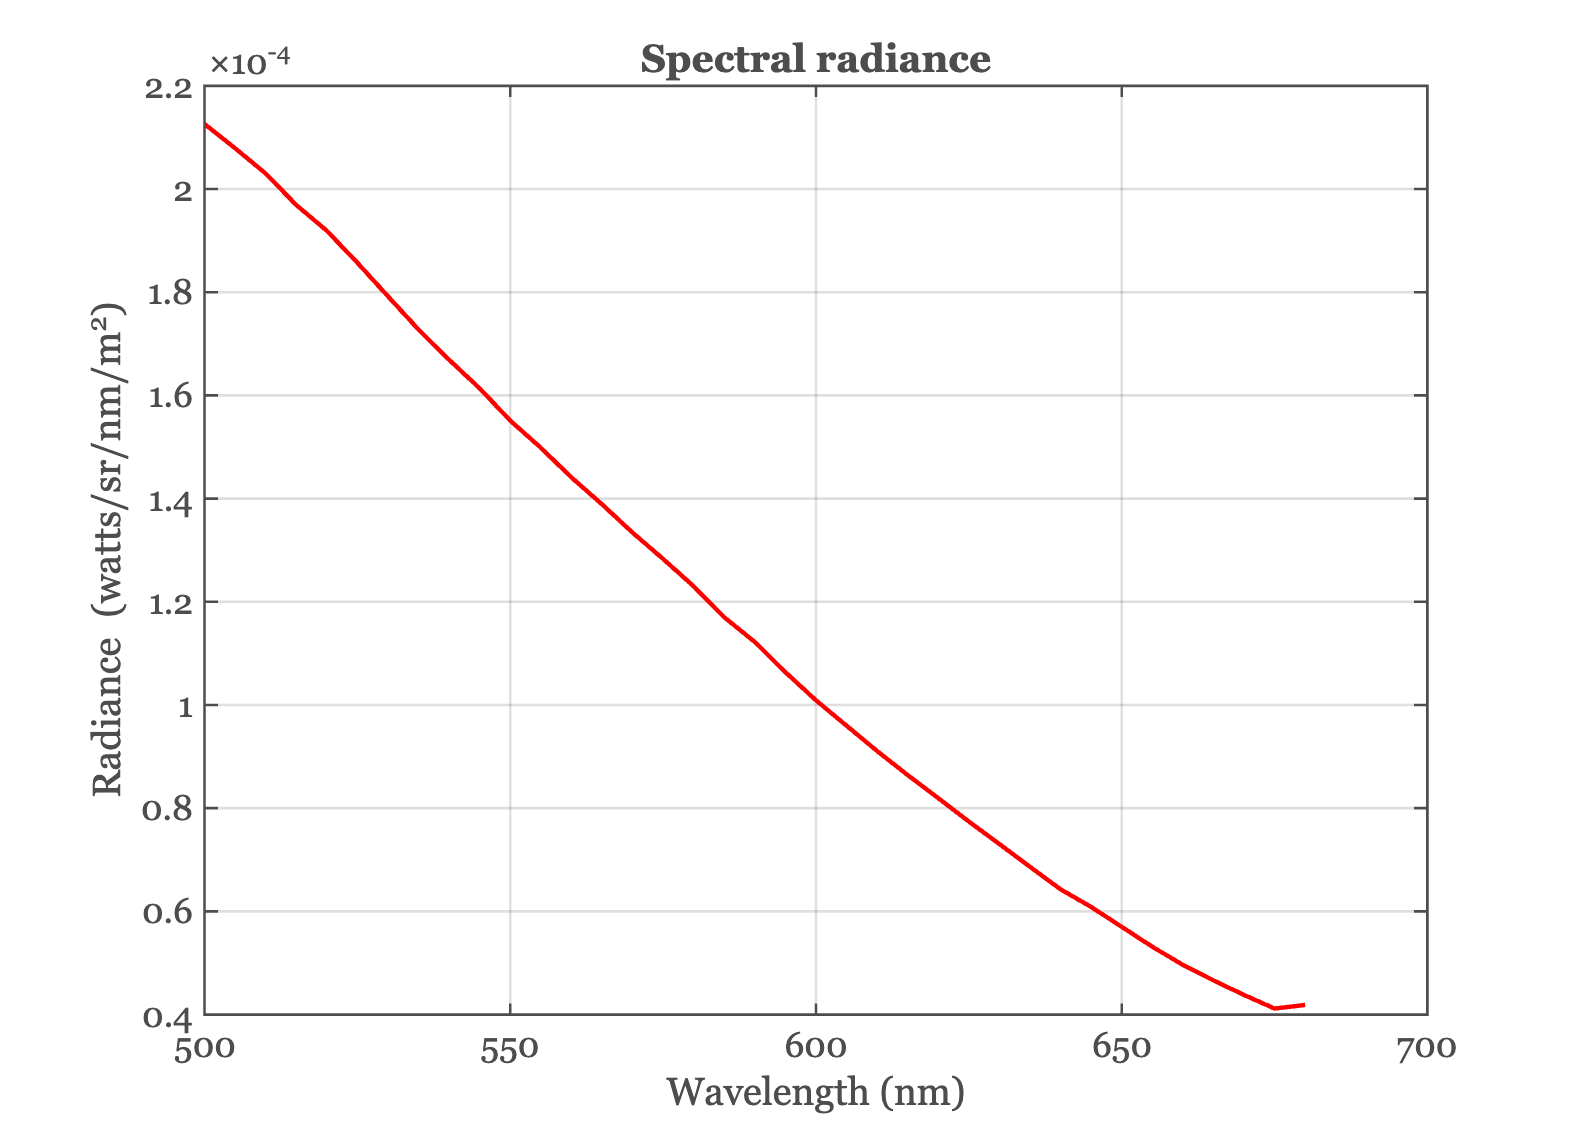

symbols = {'kx-','k*-','k^-','ko-'};
T2 = oeDatabaseLightsCreate;
unwanted415 = ieTableGet(T2,'condition','unwantedreflected','ewave',415,'elevel',910);
data415 = oeReadFiles(unwanted415,'waves',waves);
plotRadiance(waves,data415);

% exportgraphics(gcf,'unwanted415.png','Resolution',150);

## Fluorescence and reflectance for each subject - tongue

Maximum intensity here.  The notebook analysis shows it is remains about 10x brighter at lower excitation intensities as well.  As expected.

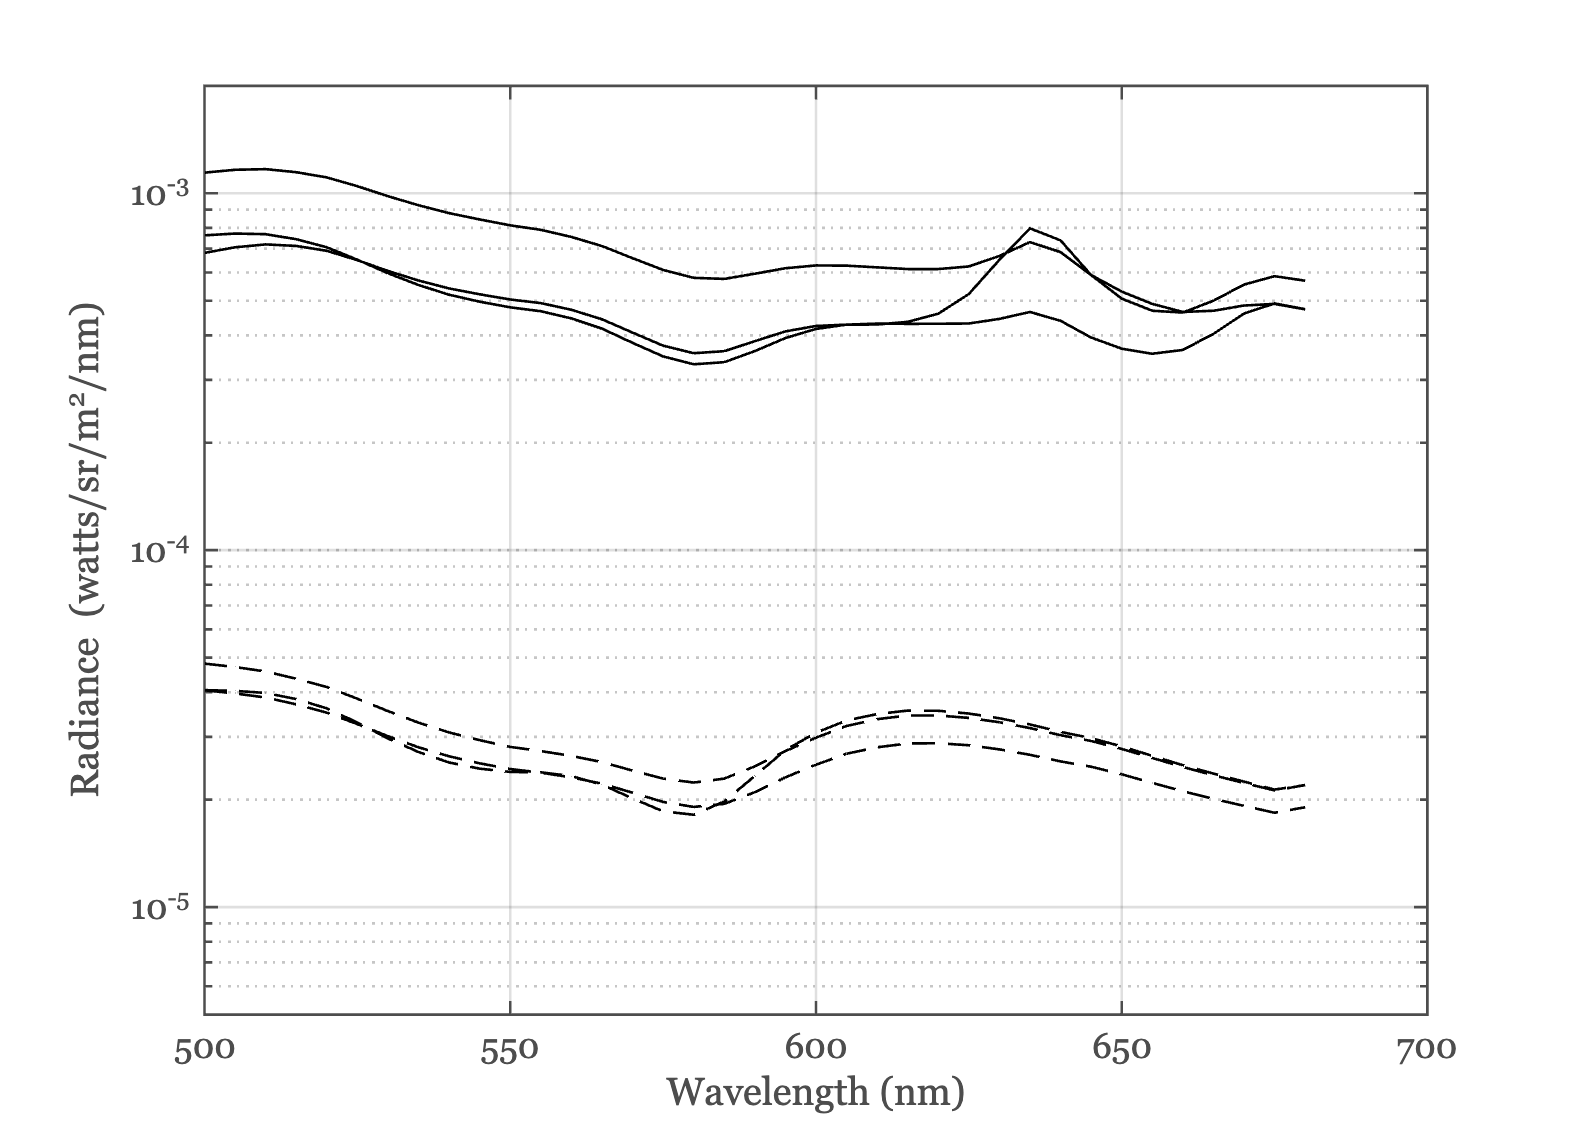

data = zeros(numel(waves),numel(subjects));
predicted = data;
for ss = 2:numel(subjects)
    tongueFiles = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files','subject',subjects{ss});
    tmp = oeReadFiles(tongueFiles,'waves',waves,'normalized wave',nWave);
    data(:,ss) = mean(tmp,2);

    % Reflected data
    subDir = sprintf('S%d',ss);
    fname = fullfile(oeTongueLipRootPath,'data','Reflectance',subDir,'tongueReflectance.mat');
    tongueReflectance = ieReadSpectra(fname,waves);
    predicted(:,ss) = data415.*tongueReflectance;
end

ieFigure;
plot(waves,data(:,2:4),'k-',waves,predicted(:,2:4),'k--');
set(gca,'ylim',[0.5*10^-5 2*10^-3]);
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/m^2/nm)'); set(gca,'yscale','log');
exportgraphics(gcf,'figure2B.png','Resolution',150);

## Fluorescence and reflectance for each subject - lip

Maximum intensity here.  The notebook analysis shows it is still about 10x brighter at lower excitation intensities.

data = zeros(numel(waves),numel(subjects));
predicted = data;
for ss = 2:numel(subjects)
    lipFiles = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910,'return','files','subject',subjects{ss});
    tmp = oeReadFiles(lipFiles,'waves',waves,'normalized wave',nWave);
    data(:,ss) = mean(tmp,2);

    % Reflected data
    subDir = sprintf('S%d',ss);
    fname = fullfile(oeTongueLipRootPath,'data','Reflectance',subDir,'lipReflectance.mat');
    tongueReflectance = ieReadSpectra(fname,waves);
    predicted(:,ss) = data415.*tongueReflectance;
end

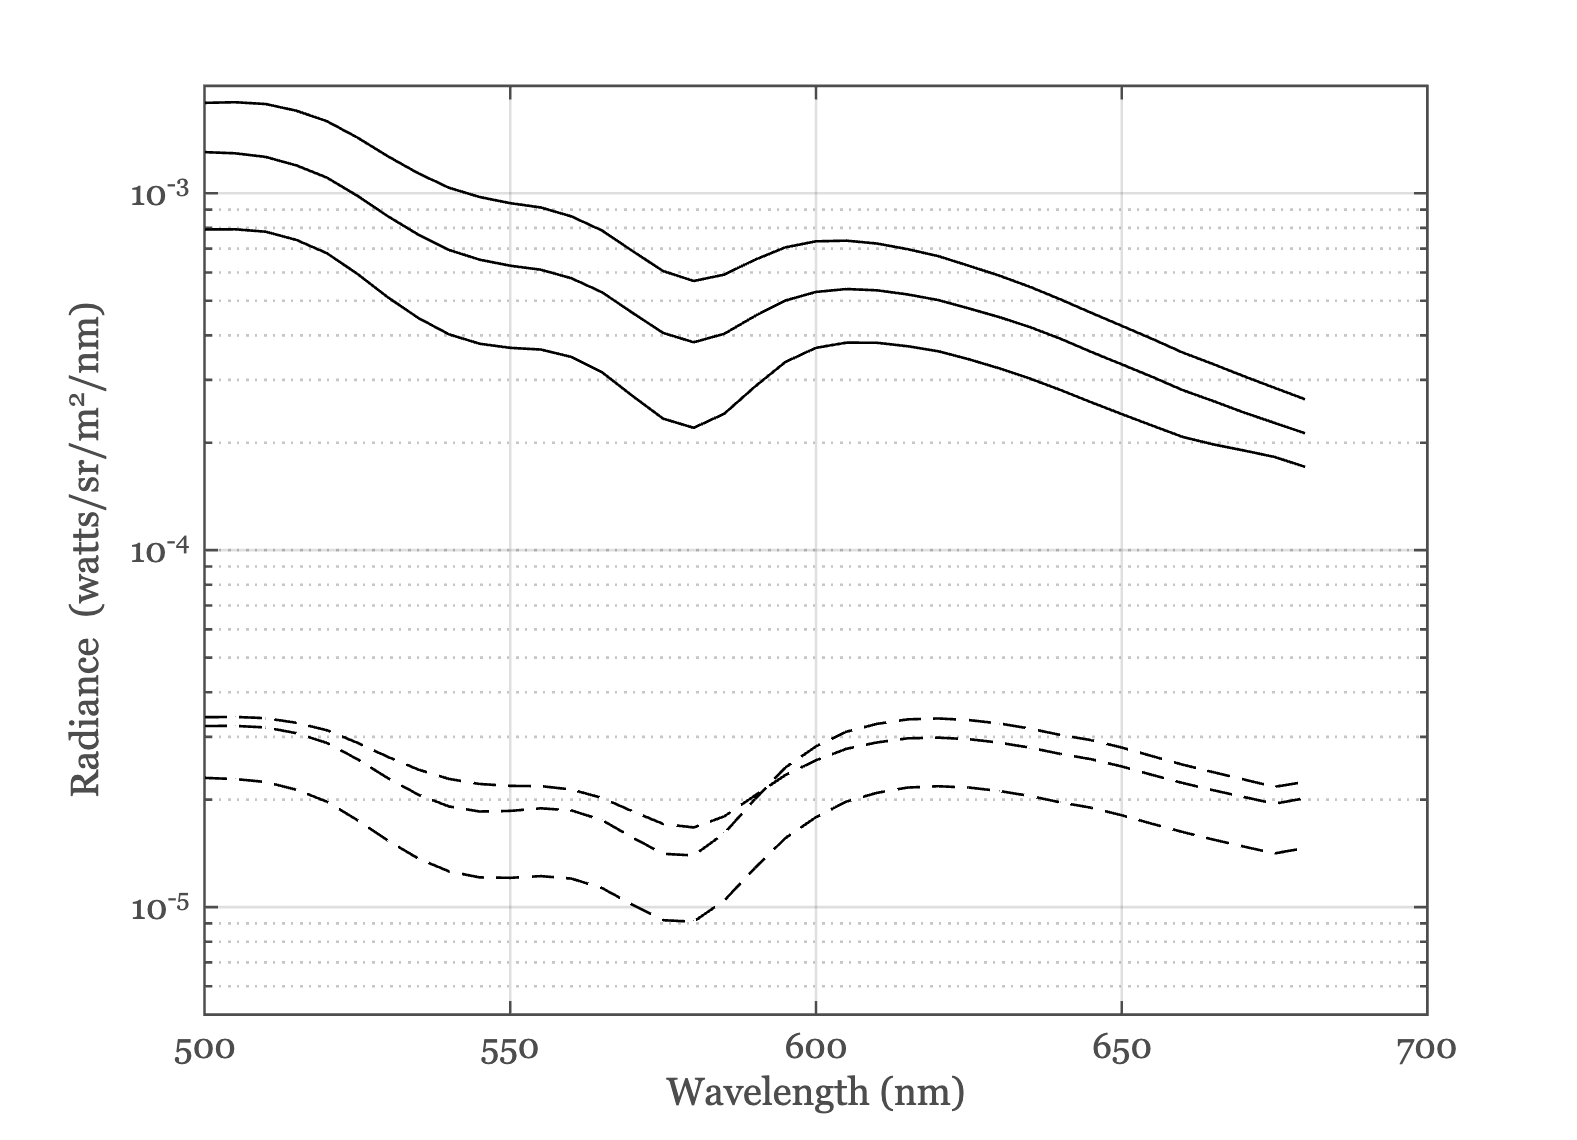

ieFigure;
plot(waves,data(:,2:4),'k-',waves,predicted(:,2:4),'k--');
set(gca,'ylim',[0.5*10^-5 2*10^-3]);
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/m^2/nm)'); set(gca,'yscale','log');
set(gca,'ylim',[0.5*10^-5 2*10^-3]);
exportgraphics(gcf,'figure2A.png','Resolution',150);